# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## 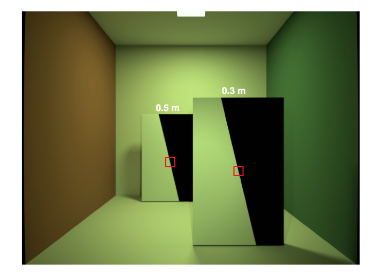

**Figure 6**. The line spread function (LSF) was estimated from a simulated image the contained two slanted edges. These were positioned at two different depths (0.3 m and 0.5 m from the camera position) and field heights (0.7 mm and 0.8 mm) that matched the distances and field heights of the slanted edge target that was captured with the Google Pixel 4a camera. The LSF is estimated by selecting a small region of the slanted edge and using measurements from multiple rows to estimate a densely sampled step-edge response. The derivative of the step-edge response is the LSF. The modulation transfer function (MTF) is the magnitude of the Fourier Transform of the LSF.

**Downloads**

Prior to running these scripts, please download the data we have prepared on the Stanford digital Repository at this URL

     [https://purl.stanford.edu/jz021qy7454](https://purl.stanford.edu/jz021qy7454) 

These are zip files that need to be uncompressed.  You may need to set the path correctly for your computer to read in the prepared files.

### Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

% Make sure you have iset3d-v3 on your path.  This script was tested
% on the Main branch with the latest release, a
% Create Cornell Box recipe
thisR = cbBoxCreate;

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall


### Add a distant light in front of box for visualization


distlight = piLightCreate('Dist light', 'type', 'spot',...
                    'spectrum spd', 'cbox-lights-1',...
                    'specscale', 0.001,...
                    'from', [0.008 0.15 -0.3],...
                    'to', [0.008 0.03 0],...
                    'cameracoordinate', false,...
                    'coneangle', 60,...
                    'conedeltaangle',50);
thisR.set('light', 'add', distlight);     

### Adjust the position of the camera

The origin is in the bottom center of the box, the depth of the box is  30 cm, the camera is 25 cm from the front edge. The position of the  camera should be set to 25 + 15 = 40 cm from the origin

from = thisR.get('from');
newFrom = [0 0.115 -0.40];% This is the place where we can see more
thisR.set('from', newFrom);
newTo = newFrom + [0 0 1]; % The camera is horizontal
thisR.set('to', newTo);

%% Remove cubes
thisR.set('assets', 'CubeSmall_B', 'chop');
thisR.set('assets', 'CubeLarge_B', 'chop');

%% Add slanted edge
assetTreeName = 'slantedbar';
slantedBar = piAssetLoad(assetTreeName);
piRecipeMerge(thisR, slantedBar.thisR, 'node name', slantedBar.mergeNode);

scale = thisR.get('asset', slantedBar.mergeNode, 'scale');
thisR.set('asset', slantedBar.mergeNode, 'scale', [0.08 0.13 0.01]*1.2);
% thisR.set('asset', slantedBar.mergeNode, 'world rotate', [0 0 180]);

thisR.set('asset', slantedBar.mergeNode, 'world position', [-0.04 0.08 0.10]);

% Now get a copy of the slanted bar and place it on a different position
[~, slantedBar2] = piObjectInstanceCreate(thisR, slantedBar.mergeNode);

thisR.set('asset', slantedBar2, 'world position', [0.05 0.08 -0.10]);

%% Specify rendering settings

% Use [4032 3024] for high quality rendering.
% The script runs at 1/16th by default.
thisR.set('film resolution',[4032 3024]/16); 

% 1024 for high quality rendering
nRaysPerPixel = 256;   

thisR.set('rays per pixel',nRaysPerPixel);
thisR.set('nbounces', 2);
thisR.set('fov', 77);
thisR.set('film diagonal', 7.056); % mm

%% Create lens
lensFile = fullfile(cboxRootPath, 'data', 'lens', 'pixel4a-rearcamera-ellipse-raytransfer.json');
cameraRTF = piCameraCreate('raytransfer','lensfile',lensFile);

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


thisR.camera = cameraRTF;

thisFilmDist = 0.57624; % in mm
thisR.set('film distance', thisFilmDist/1000);
piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference/CornellBoxReference.pbrt


[oiTemp, result] = piRender(thisR, 'render type', 'radiance', 'scale illuminance', false,...
                        'docker image','vistalab/pbrt-v3-spectral:raytransfer-ellipse');

Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference" --volume="/Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference":"/Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference/renderings/CornellBoxReference.dat /Users/wandell/Documents/MATLAB/isetprojects/iset3d-v3/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  455.2 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


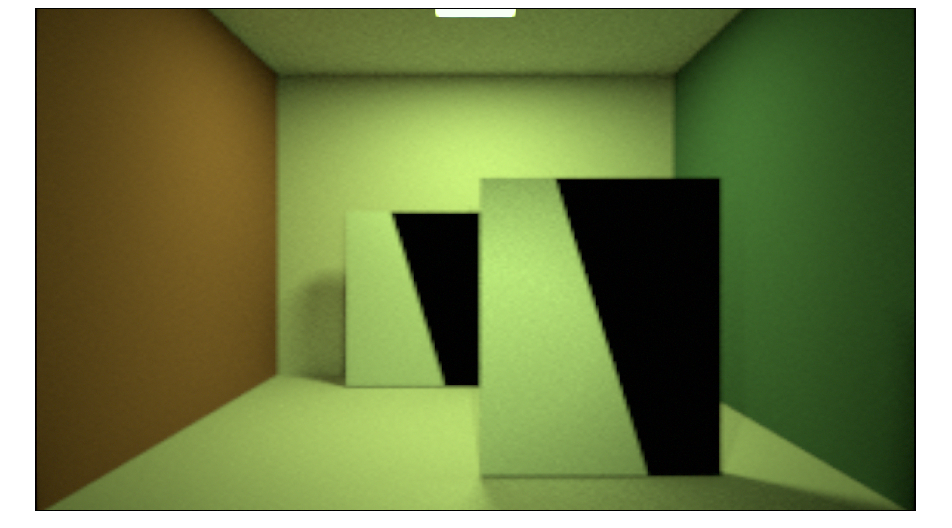

oiName = sprintf(['CBRTF_slantedEdge_filmdist_' num2str(thisFilmDist) 'mm']);
oiSlantedBar = oiSet(oiTemp, 'name', oiName);

%% Sensor compute part
oi = oiSlantedBar;
sensor = cbSensorCreate;
sensor = sensorSetSizeToFOV(sensor, oiGet(oi, 'fov'), oi);
sensor = sensorSet(sensor, 'exp time', 0.1481);
sensor = sensorCompute(sensor, oi);

ip = cbIpCompute(sensor);

img = ipGet(ip, 'srgb');
ieNewGraphWin; imagesc(img); axis off; truesize; % Low resolution image

This image is blurry because we ran the simulation at low spatial resolution.  For the publication data, we used the higher resolution as described in the notes above.  This is 1/16th of the resolution we used in the paper.

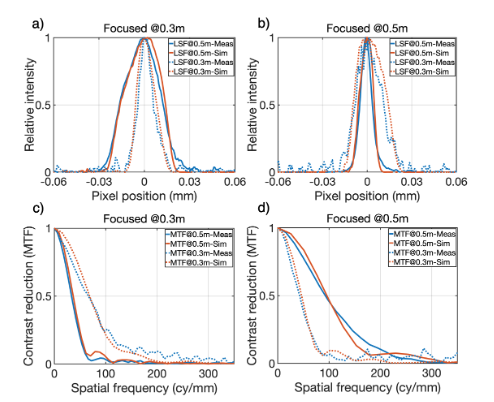

**Figure 7**. Comparison of the spatial blur and depth of field. (a,b). The measured (blue) and simulated (red) LSFs are compared. The curves show the LSFs for lines at two different distances. Panel a shows data with a focal distance of 0.3m and Panel b with the focal distance of 0.5m. In each case the narrow LSF is for the line at the focal distance, and the broader LSF is for the line that is too near or too far. (c,d) The LSF data are transformed into the corresponding MTF curves where the broader MTF is for the line that is in focus. The measured and simulated lines were at slightly different field heights (0.7 mm and 0.8 mm), but this difference did not have a substantial impact on the measurements.

ieInit;

%% Measurement: focus back
% Distance 1: 0.5m, 0.3m
% Load resolution chart
measPath = fullfile(cboxRootPath, 'local', 'measurement',...
                'resolution_targets');
% Back
dngFileBack = fullfile('distance_1', 'focus_back', '0.2s_exp',...
                'IMG_20210106_171618.dng');
            
[sensorMeasBack, ~, ipMeasBack] = cbDNGRead(fullfile(measPath, dngFileBack), 'demosaic', true);
dx = sensorGet(sensorMeasBack,'pixel width','mm');

roiIntMeasBack = [1953        2087          43          68];
mtfDataMeasBack = cbMTFAnalysis(ipMeasBack, roiIntMeasBack, dx);
filmHeightMeasBack = cbSensorLoc2FilmHeight(sensorMeasBack,...
                                    [roiIntMeasBack(2), roiIntMeasBack(1)]);

% Front
dngFileFront = fullfile('distance_1', 'focus_back', '0.4s_exp',...
                'IMG_20210106_171705.dng');
[sensorMeasFront, ~, ipMeasFront] = cbDNGRead(fullfile(measPath, dngFileFront), 'demosaic', true);

roiIntMeasFront = [2518 1557 97 144]; 
mtfDataMeasFront = cbMTFAnalysis(ipMeasFront, roiIntMeasFront, dx);
filmHeightMeasFront = cbSensorLoc2FilmHeight(sensorMeasFront,...
                                    [roiIntMeasFront(2), roiIntMeasFront(1)]);
                                

### Simulation: focus back

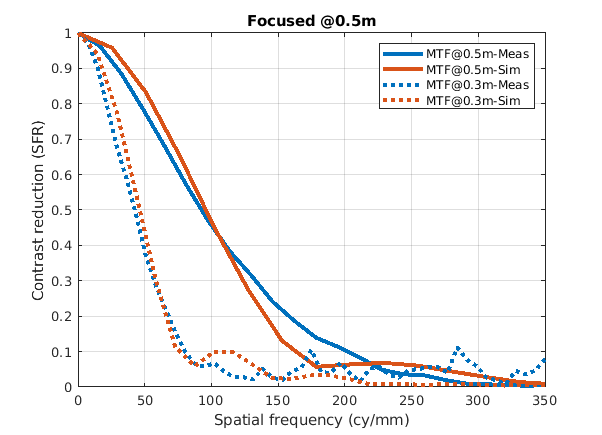

% Load oi
% Focus back: filmdist_0.49234mm
mtfPath = fullfile(cboxRootPath, 'local', 'simulation', 'slantedBar');

mtfFile = 'CBRTF_slantedEdge_filmdist_0.49234mm.mat';

load(fullfile(mtfPath, mtfFile));

meanIllu = oiGet(oiSlantedBar, 'mean illuminance');
oiSlantedBarAdj = oiSet(oiSlantedBar, 'mean illuminance', meanIllu/2);
sensorSim = sensorMeasBack;
sensorSim = cbSensorCompute(sensorSim, oiSlantedBarAdj);
ipSim = cbIpCompute(sensorSim);

roiIntSimBack = [1829 2067 27 46];
mtfDataSimBack = cbMTFAnalysis(ipSim, roiIntSimBack, dx);
filmHeightSimBack = cbSensorLoc2FilmHeight(sensorSim,...
                                    [roiIntSimBack(2), roiIntSimBack(1)]);
roiIntSimFront = [2511        1667          48          127];
mtfDataSimFront = cbMTFAnalysis(ipSim, roiIntSimFront, dx);
filmHeightSimFront = cbSensorLoc2FilmHeight(sensorSim,...
                                    [roiIntSimFront(2), roiIntSimFront(1)]);
                                
%% Figure plot: Focus back
freqMeasBack = mtfDataMeasBack.freq + 0.0001;
mtfMeasBack = mtfDataMeasBack.mtf(:,4);
lsfxMeasBack = mtfDataMeasBack.lsfx;
lsfMeasBack = mtfDataMeasBack.lsf;
freqSimBack = mtfDataSimBack.freq + 0.0001;
mtfSimBack = mtfDataSimBack.mtf(:,4);
lsfxSimBack = mtfDataSimBack.lsfx;
lsfSimBack = mtfDataSimBack.lsf;

freqMeasFront = mtfDataMeasFront.freq + 0.0001;
mtfMeasFront = mtfDataMeasFront.mtf(:,4);
lsfxMeasFront = mtfDataMeasFront.lsfx;
lsfMeasFront = mtfDataMeasFront.lsf;
freqSimFront = mtfDataSimFront.freq + 0.0001;
mtfSimFront = mtfDataSimFront.mtf(:,4);
lsfxSimFront = mtfDataSimFront.lsfx;
lsfSimFront = mtfDataSimFront.lsf;

% MTF curve
ieNewGraphWin; hold all; 
plot(freqMeasBack, mtfMeasBack,'Color', [0, 0.4410, 0.7410],'LineWidth', 3);
plot(freqSimBack, mtfSimBack, 'Color', [0.85, 0.325, 0.098],'LineWidth', 3);
plot(freqMeasFront, mtfMeasFront, ':', 'Color', [0, 0.441, 0.741], 'LineWidth', 3);
plot(freqSimFront, mtfSimFront, ':', 'Color',[0.85, 0.325, 0.098], 'LineWidth', 3);
box on; grid on;
xlabel('Spatial frequency (cy/mm)'); ylabel('Contrast reduction (SFR)');
xlim([0 350]); ylim([0 1])
legend('MTF@0.5m-Meas', 'MTF@0.5m-Sim', 'MTF@0.3m-Meas', 'MTF@0.3m-Sim');
title('Focused @0.5m');

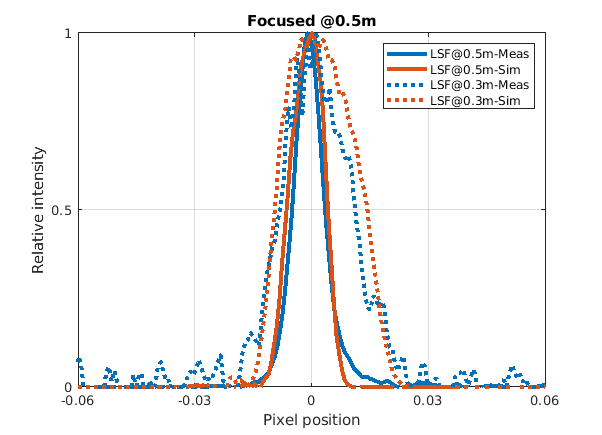

% LSF
ieNewGraphWin; hold all;
plot(lsfxMeasBack, lsfMeasBack, 'Color', [0, 0.4410, 0.7410], 'LineWidth', 3);
% Slight shift for curve allignment
plot(lsfxSimBack-0.0009, lsfSimBack, 'Color', [0.85, 0.325, 0.098],'LineWidth', 3);
plot(lsfxMeasFront+0.0050, lsfMeasFront, ':', 'Color', [0, 0.441, 0.741], 'LineWidth', 3);
plot(lsfxSimFront+0.002, lsfSimFront, ':', 'Color',[0.85, 0.325, 0.098],'LineWidth', 3);
xlim([-0.06 0.06]); ylim([0 1]); xticks(-0.06:0.03:0.06); yticks(0:0.5:1)
box on; grid on; 
legend('LSF@0.5m-Meas', 'LSF@0.5m-Sim', 'LSF@0.3m-Meas', 'LSF@0.3m-Sim');
title('Focused @0.5m');
xlabel('Pixel position'); ylabel('Relative intensity');

## Measurement: focus front

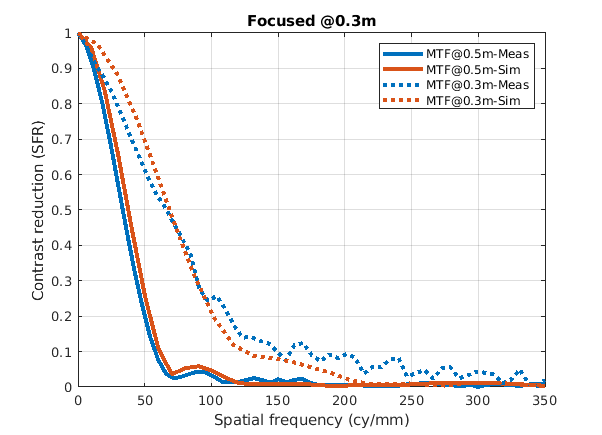


% Back
dngFileBack2 = fullfile('distance_1', 'focus_front', '0.2s_exp',...
                'IMG_20210106_171803.dng');
            
[sensorMeasBack2, ~, ipMeasBack2] = cbDNGRead(fullfile(measPath, dngFileBack2), 'demosaic', true);
dx = sensorGet(sensorMeasBack2,'pixel width','mm');

roiIntMeasBack2 = [1924        2055         118         161];
mtfDataMeasBack2 = cbMTFAnalysis(ipMeasBack2, roiIntMeasBack2, dx);
filmHeightMeasBack2 = cbSensorLoc2FilmHeight(sensorMeasBack,...
                                    [roiIntMeasBack2(2), roiIntMeasBack2(1)]);

% Front
dngFileFront2 = fullfile('distance_1', 'focus_front', '0.4s_exp',...
                'IMG_20210106_171912.dng');
[sensorMeasFront2, ~, ipMeasFront2] = cbDNGRead(fullfile(measPath, dngFileFront2), 'demosaic', true);

roiIntMeasFront2 = [2515 1475 109 195];
mtfDataMeasFront2 = cbMTFAnalysis(ipMeasFront2, roiIntMeasFront2, dx);
filmHeightMeasFront2 = cbSensorLoc2FilmHeight(sensorMeasFront,...
                                    [roiIntMeasFront2(2), roiIntMeasFront2(1)]);


%% Simulation: Focus front
mtfPath = fullfile(cboxRootPath, 'local', 'simulation', 'slantedBar');

% Front: filmdist 0.57624mm.
mtfFile = 'CBRTF_slantedEdge_filmdist_0.57624mm.mat';

load(fullfile(mtfPath, mtfFile));

meanIllu2 = oiGet(oiSlantedBar, 'mean illuminance');
oiSlantedBarAdj2 = oiSet(oiSlantedBar, 'mean illuminance', meanIllu2/2);
sensorSim2 = sensorMeasBack;
sensorSim2 = cbSensorCompute(sensorSim2, oiSlantedBarAdj2);
ipSim2 = cbIpCompute(sensorSim2);

% roiIntSimBack = [1729 1665 72 145];
roiIntSimBack2 = [1824 2025 70 183];
mtfDataSimBack2 = cbMTFAnalysis(ipSim2, roiIntSimBack2, dx);
filmHeightSimBack2 = cbSensorLoc2FilmHeight(sensorSim2,...
                                    [roiIntSimBack2(2), roiIntSimBack2(1)]);

roiIntSimFront2 = [2394 1173 48 91];
mtfDataSimFront2 = cbMTFAnalysis(ipSim2, roiIntSimFront2, dx);
filmHeightSimFront2 = cbSensorLoc2FilmHeight(sensorSim2,...
                                    [roiIntSimFront2(2), roiIntSimFront2(1)]);
%% Figure plot: focus front
freqMeasBack2 = mtfDataMeasBack2.freq + 0.0001;
mtfMeasBack2 = mtfDataMeasBack2.mtf(:,4);
lsfxMeasBack2 = mtfDataMeasBack2.lsfx;
lsfMeasBack2 = mtfDataMeasBack2.lsf;
freqSimBack2 = mtfDataSimBack2.freq + 0.0001;
mtfSimBack2 = mtfDataSimBack2.mtf(:,4);
lsfxSimBack2 = mtfDataSimBack2.lsfx;
lsfSimBack2 = mtfDataSimBack2.lsf;

freqMeasFront2 = mtfDataMeasFront2.freq + 0.0001;
mtfMeasFront2 = mtfDataMeasFront2.mtf(:,4);
lsfxMeasFront2 = mtfDataMeasFront2.lsfx;
lsfMeasFront2 = mtfDataMeasFront2.lsf;
freqSimFront2 = mtfDataSimFront2.freq + 0.0001;
mtfSimFront2 = mtfDataSimFront2.mtf(:,4);
lsfxSimFront2 = mtfDataSimFront2.lsfx;
lsfSimFront2 = mtfDataSimFront2.lsf;

ieNewGraphWin; hold all; 
plot(freqMeasBack2, mtfMeasBack2, 'Color', [0, 0.4410, 0.7410], 'LineWidth', 3);
plot(freqSimBack2, mtfSimBack2, 'Color', [0.85, 0.325, 0.098], 'LineWidth', 3);
plot(freqMeasFront2, mtfMeasFront2, ':','Color', [0, 0.4410, 0.7410], 'LineWidth', 3);
plot(freqSimFront2, mtfSimFront2, ':','Color', [0.85, 0.325, 0.098], 'LineWidth', 3);
box on; grid on;
xlabel('Spatial frequency (cy/mm)'); ylabel('Contrast reduction (SFR)');
xlim([0 350]); ylim([0 1])
legend('MTF@0.5m-Meas', 'MTF@0.5m-Sim', 'MTF@0.3m-Meas', 'MTF@0.3m-Sim');
title('Focused @0.3m');

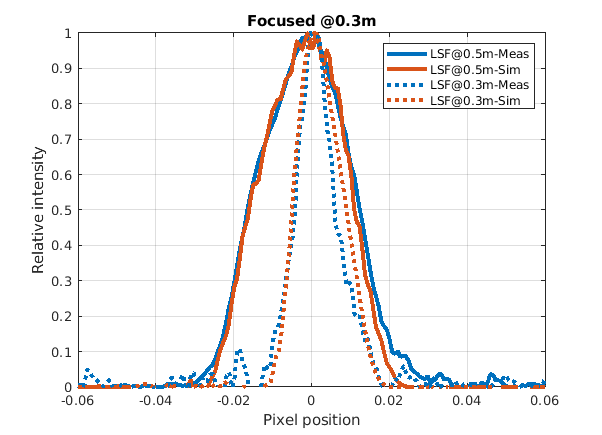


% LSF
ieNewGraphWin; hold all;
plot(lsfxMeasBack2+0.0008, lsfMeasBack2, 'Color', [0, 0.4410, 0.7410], 'LineWidth', 3);
plot(lsfxSimBack2-0.002, lsfSimBack2, 'Color', [0.85, 0.325, 0.098], 'LineWidth', 3);
plot(lsfxMeasFront2-0.0012, lsfMeasFront2, ':','Color', [0, 0.4410, 0.7410], 'LineWidth', 3);
plot(lsfxSimFront2+0.00175, lsfSimFront2, ':','Color', [0.85, 0.325, 0.098], 'LineWidth', 3);
box on; grid on;
xlabel('Pixel position'); ylabel('Relative intensity');
xlim([-0.06 0.06]); ylim([0 1])
legend('LSF@0.5m-Meas', 'LSF@0.5m-Sim', 'LSF@0.3m-Meas', 'LSF@0.3m-Sim');
title('Focused @0.3m');